Average filter for each pixel calculate the avg val of its 8-neighbor and itself, looks artificial and fake

Gaussian filter create a Gaussian mask based on normal distribution

## 11. High boost filter

img = imread('images\cameraman.tif');
% the emphasis is on the middle pixel
kernel = [-1 -1 -1; -1 11 -1; -1 -1 -1]/9

kernel =    -0.1111   -0.1111   -0.1111
   -0.1111    1.2222   -0.1111
   -0.1111   -0.1111   -0.1111


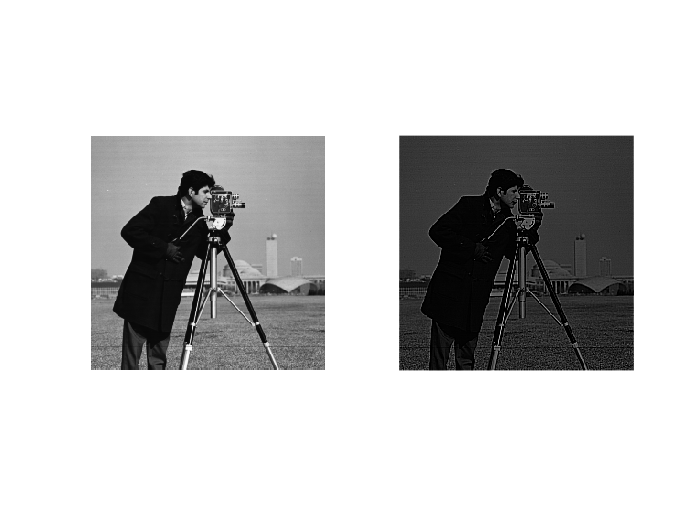

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

% the emphasis is on the edges because sum of kernel vals is zero
kernel = [-1 -1 -1; -1 8 -1; -1 -1 -1]/9

kernel =    -0.1111   -0.1111   -0.1111
   -0.1111    0.8889   -0.1111
   -0.1111   -0.1111   -0.1111


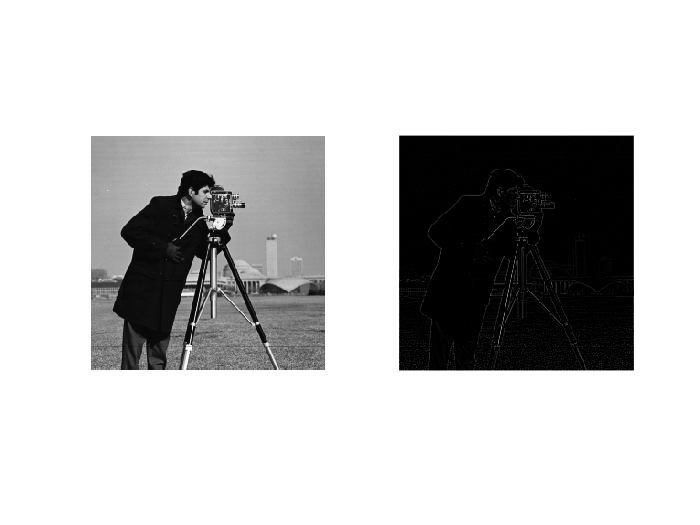

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

% the sum of the kernel is one; the val on center is larger than neighbors
kernel = [1 1 1; 1 12 1; 1 1 1]/20

kernel =     0.0500    0.0500    0.0500
    0.0500    0.6000    0.0500
    0.0500    0.0500    0.0500


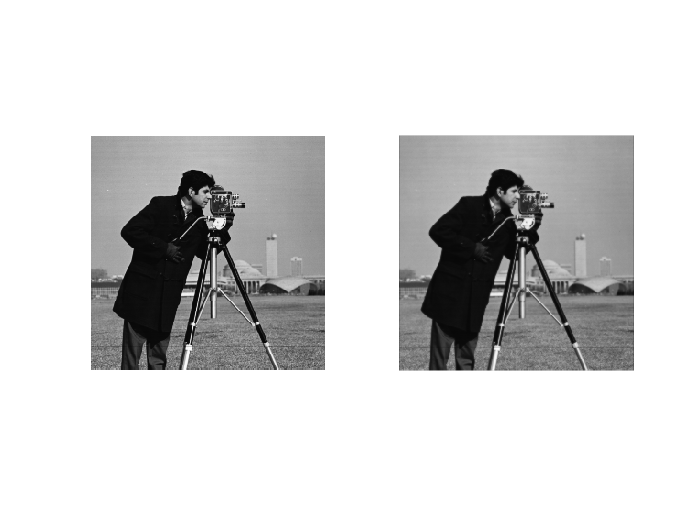

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

% the sum of the kernel is one; the val on center is larger than neighbors
kernel = [1 1 1; 1 18 1; 1 1 1]/20

kernel =     0.0500    0.0500    0.0500
    0.0500    0.9000    0.0500
    0.0500    0.0500    0.0500


sum(kernel,'all')

ans = 1.3000

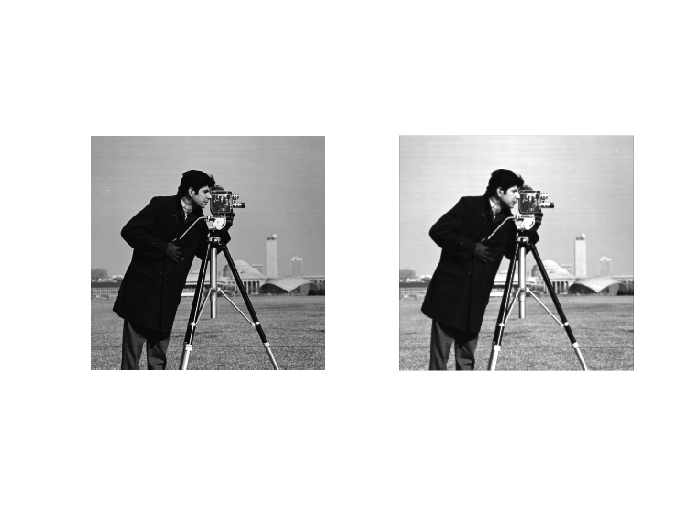

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

% the sum of the kernel is zero; horizontal edge detection
kernel = [-1 -1 -1; 2 2 2; -1 -1 -1]

kernel =     -1    -1    -1
     2     2     2
    -1    -1    -1


sum(kernel,'all')

ans = 0

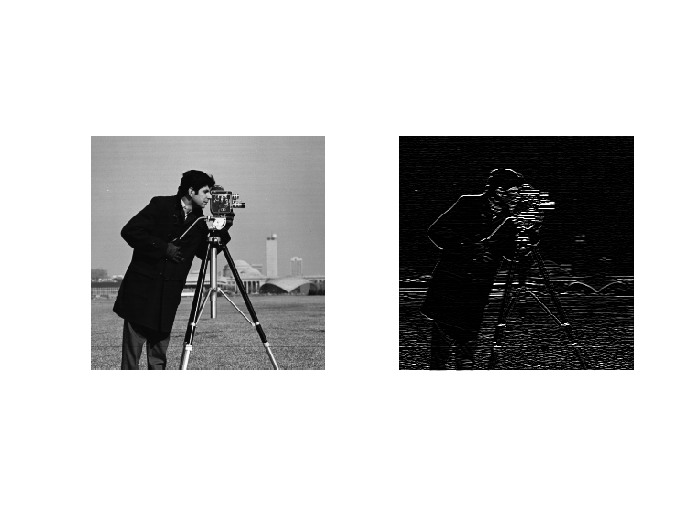

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

% the sum of the kernel is zero; horizontal edge detection
kernel = [-1 -1 -1; 2 2 2; -1 -1 -1]*10

kernel =    -10   -10   -10
    20    20    20
   -10   -10   -10


sum(kernel,'all')

ans = 0

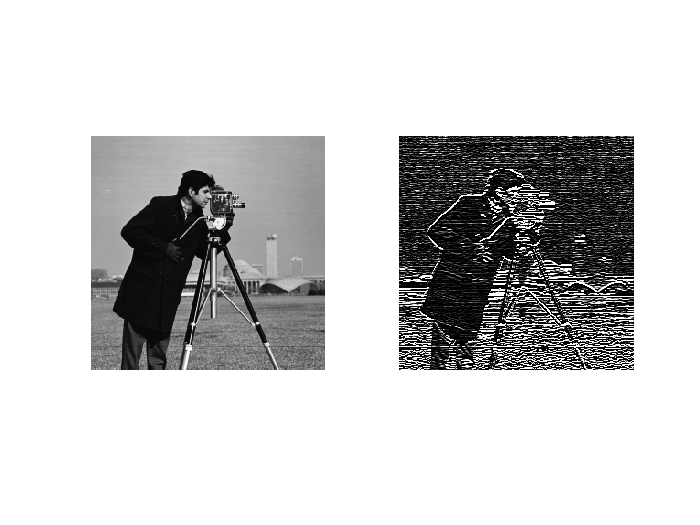

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

% the sum of the kernel is zero; vertical edge detection
kernel = [-1 2 -1; -1 2 -1; -1 2 -1]

kernel =     -1     2    -1
    -1     2    -1
    -1     2    -1


sum(kernel,'all')

ans = 0

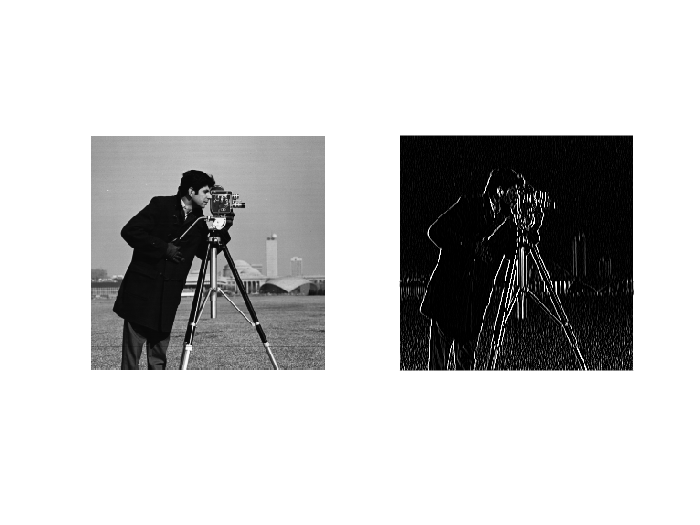

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

% the sum of the kernel is zero; diogonal edge detection
kernel = [2 -1 -1; -1 2 -1; -1 -1 2]

kernel =      2    -1    -1
    -1     2    -1
    -1    -1     2


sum(kernel,'all')

ans = 0

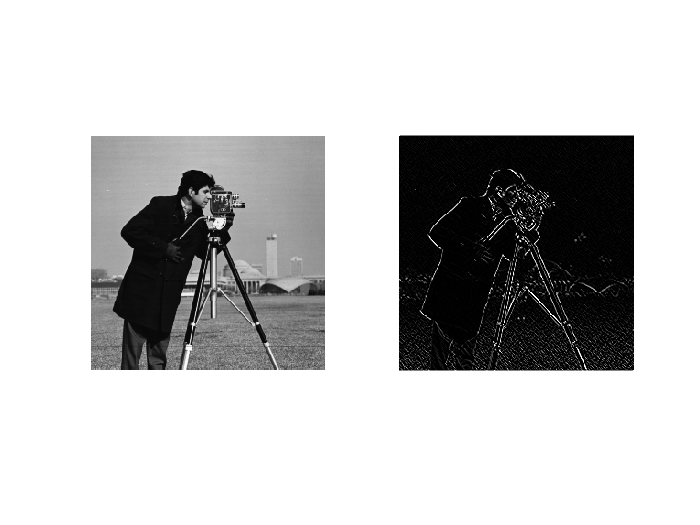

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

% the sum of the kernel is zero; emphasis on center edge detection
kernel = [-1 -1 -1; -1 8 -1; -1 -1 -1]

kernel =     -1    -1    -1
    -1     8    -1
    -1    -1    -1


sum(kernel,'all')

ans = 0

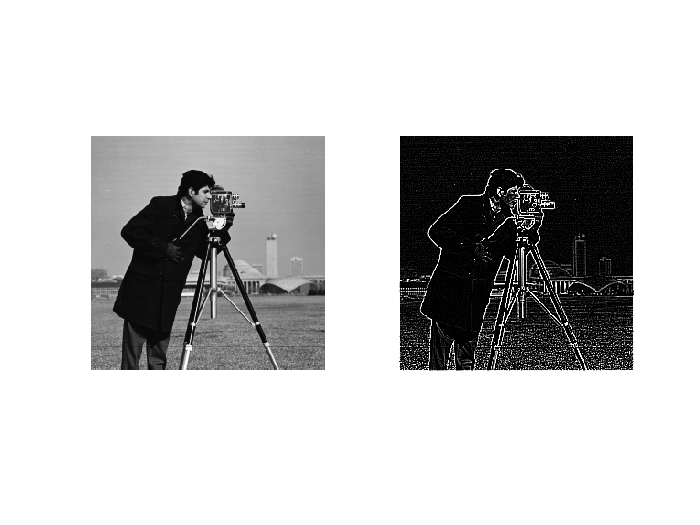

img_res = imfilter(img, kernel, 'conv');
figure, subplot(1,2,1), imshow(img);
subplot(1,2,2), imshow(img_res);

## 12. Diagonal line enhancement